# Tabletop problem for study 

This livescript builds a tabletop planning problem that consists of 

- a width x height world grid.

- an agent, can be a robot, satellite, uav, etc. The agent can move (up, down, left, right) or perform other actions, which deplete the battery

- a discretized battery model (4 states, [1,2,3,4], 1 is fully charged to steady state, 2 is steady state, 3 is steady to decline, 4 is decline - end of charge. [wip] --> moving one "normal" square depletes 3% soc, moving one "bad" square depletes 5% soc, taking a picture depletes 1%, transmitting the picture depletes 2% (some of this isn't implemented yet)

## General Setup

- The map

width = 8;
height = 8;

% start location
start = [1,1];
finish = start;

% location prototype
location.type = "normal"; 
location.label = "";

% map is a matrix of structs
map = repmat(location, 8, 8);

- The agent

agent.type = "robot";
agent.location = start;
agent.distance = 0;
agent.direction = '^';
agent.battery = [3.04 3.101 3.159 3.212 3.28 3.35 3.4 3.46 3.51 3.58 3.65 3.7 3.75 3.78 3.81 3.84 3.86 3.88 3.9 3.92 3.94 3.95 3.96 3.97 3.98 3.99 3.995 4 4.007 4.015 4.02 4.023 4.027 4.035 4.04 4.042 4.043 4.045 4.047 4.048 4.0485 4.049 4.05 4.0505 4.051 4.0515 4.052 4.0521 4.0529 4.0532 4.0539 4.0541 4.0547 4.055 4.056 4.0565 4.0569 4.0575 4.0578 4.058 4.0581 4.0582 4.0583 4.0587 4.0589 4.059 4.0591 4.0592 4.0593 4.0594 4.0595 4.0596 4.0597 4.0598	4.06 4.0605 4.061 4.062 4.064 4.065 4.068 4.07 4.071 4.0715 4.073 4.077 4.085 4.09 4.094 4.098 4.103 4.112 4.13 4.14 4.15 4.16 4.17 4.18 4.19 4.2]; 
agent.soc = 100;
agent.batteryState = 1;
agent.locationType = location.type;
agent.cumulativeReward = int16(0);

- actions (move up, down, left, right, observe, transmit

actions = ['^', 'v', '<', '>', 'o', 't'];

## The world grid

- add "points of interest"

- References are hard-coded throughout, however their location values, lengths, and names can be changed

- Update the locations here

poi.start = agent.location;
poi.objectives = [8,5; 2,7];
poi.pitfalls = [2,5; 4,1; 6,2; 8,2];
poi.blocks = [1,4; 4,3; 6,3; 5,3; 2,2; 5,4; 5,5];

- update location names here

map(poi.start(1), poi.start(2)).type = "start";
for i=1:(length(poi.objectives))
    map(poi.objectives(i,1), poi.objectives(i,2)).type = "objective";
    map(poi.objectives(i,1), poi.objectives(i,2)).label = sprintf("O-%d", i);
end

for i=1:(length(poi.pitfalls))
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).type = "pitfall";
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).label = sprintf("P-%d", i);
end
for i=1:(length(poi.blocks))
    map(poi.blocks(i,1), poi.blocks(i,2)).type = "block";
end

### Visualize the grid world

- show location of robot and objects 

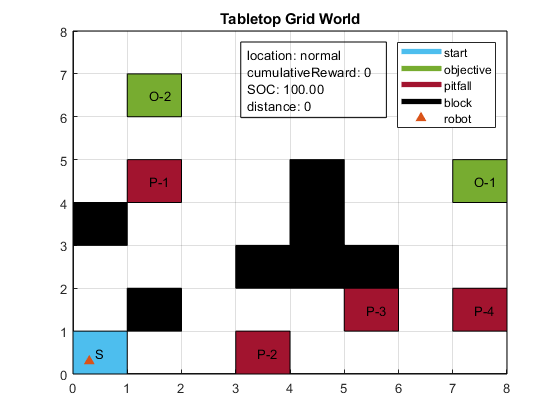

f1 = visualizeGridWorld(1, map, poi, agent);
title("Tabletop Grid World");

### [optional] Move the robot, and revisualize

- The robot cannot travel off of the grid or on a black spot

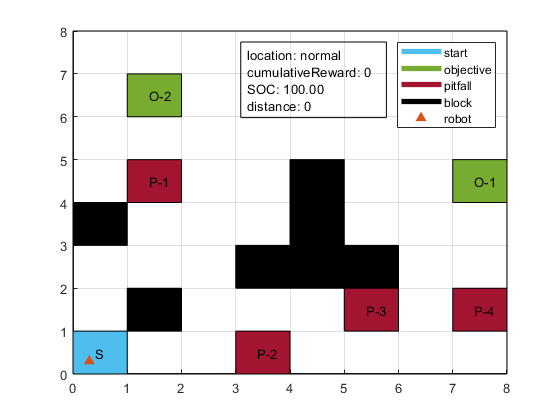

agent = moveAgent(agent, '^', 1, map, poi);

f2 = visualizeGridWorld(2, map, poi, agent);

### Robot Teleop

- reads arrow keys, q to quit (press enter to close pop up figure)

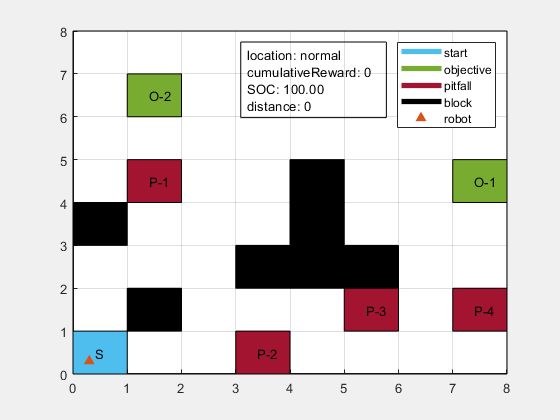

teleop(agent, 2, map, poi);

## Shortest path test

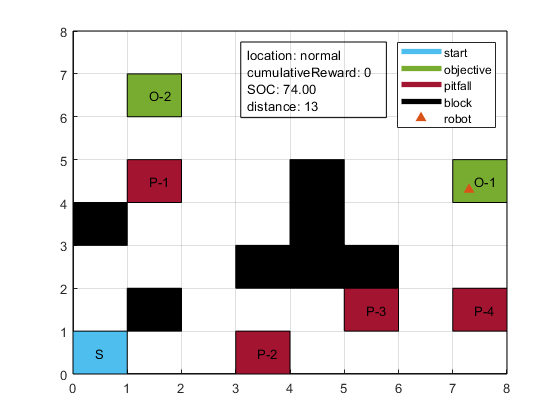

G = convert2graph(map, "block", "pitfall");
[P, d, edgepath] = shortestpath(G, 1, 40);
dirs = get_path_directions(map, P);

% reset agent if needed
agent = set_agent(map, [1,1], 0, '^', 100, 1, 0);
for i=1:length(dirs)-1
    agent = moveAgent(agent, direction_path(i), 1, map, poi);
    f3 = visualizeGridWorld(3, map, poi, agent);
    pause(.3);
end

## Keep track of State

state.location = start;
state.battery = agent.batteryState;
state.achieved1 = false;
state.achieved2 = false;



